# Tracking:

Save the bounding box results as a video:

load 'single_class_ShipDetector.mat'
rightVideo = VideoReader('C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4');

frame = readFrame(rightVideo);

while (hasFrame(rightVideo) ~= 0)
     frame = readFrame(rightVideo);
     [bbox,score, label] = detect(ship_DetectorV1,frame);
     img = insertObjectAnnotation(frame,"rectangle",bbox,label);


     imshow(img);
     drawnow
end 


## Tracking using KF

First KF implementation (TERRIBLE)

%% Parameters
load 'single_class_ShipDetector.mat'
videoFile = 'C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4';
frameRate = 12;
maxInvisible = 5;    % frames to keep a track without detection
nextTrackID = 1;     % counter for assigning unique IDs

%% Tracker storage
tracks = struct( ...
    'KF', {}, ...
    'TrackID', {}, ...
    'Age', {}, ...
    'TotalVisibleCount', {}, ...
    'ConsecutiveInvisibleCount', {});

%% Open video
video = VideoReader(videoFile);
frame = readFrame(video);

%% Main loop
while hasFrame(video)
    frame = readFrame(video);
    
    %% Detect ships
    [bboxes, scores, labels] = detect(ship_DetectorV1, frame);
    
    % Convert bboxes to centroids
    if ~isempty(bboxes)
        centroids = [bboxes(:,1)+bboxes(:,3)/2, bboxes(:,2)+bboxes(:,4)/2];
    else
        centroids = [];
    end
    
    %% Predict new locations of existing tracks
    for i = 1:length(tracks)
        tracks(i).KF.predict();
    end
    
    %% Assign detections to tracks (nearest neighbor)
    Ntracks = length(tracks);
    Ndetections = size(centroids,1);
    
    cost = zeros(Ntracks, Ndetections);
    for i = 1:Ntracks
        pred = tracks(i).KF.State([1 3]); % x, y
        for j = 1:Ndetections
            cost(i,j) = norm(pred - centroids(j,:));
        end
    end
    
    % Simple greedy assignment
    assignedTracks = zeros(1, Ndetections);
    assignedDetections = zeros(1, Ntracks);
    if ~isempty(cost)
        for j = 1:Ndetections
            [minVal, minIdx] = min(cost(:,j));
            if minVal < 50 % max distance threshold
                if ~assignedTracks(j) && ~assignedDetections(minIdx)
                    assignedTracks(j) = minIdx;
                    assignedDetections(minIdx) = j;
                end
            end
        end
    end
    
    %% Update assigned tracks
    for j = 1:Ndetections
        if assignedTracks(j)
            idx = assignedTracks(j);
            tracks(idx).KF.correct(centroids(j,:)');
            tracks(idx).Age = tracks(idx).Age + 1;
            tracks(idx).TotalVisibleCount = tracks(idx).TotalVisibleCount + 1;
            tracks(idx).ConsecutiveInvisibleCount = 0;
        else
            % Create new track
            %Assume constant velocity
            motionModel = "ConstantVelocity";
            initialLoc = centroids(j,:)';
            %variance in pos and vel
            initialError = [1 25];
            motionNoise = [1 25];
            %assume high meas noise to make the model predict more biasedly on
            %estimated position not bbox
            measurementNoise = 100;
            kf = configureKalmanFilter(motionModel,initialLoc,initialError, motionNoise, measurementNoise); 
            newTrack = struct( ...
                'KF', kf, ...
                'TrackID', nextTrackID, ...
                'Age', 1, ...
                'TotalVisibleCount', 1, ...
                'ConsecutiveInvisibleCount', 0);
            tracks(end+1) = newTrack;
            nextTrackID = nextTrackID + 1;
        end
    end
    
    %% Increment invisible counters for unassigned tracks
    for i = 1:Ntracks
        if ~assignedDetections(i)
            tracks(i).ConsecutiveInvisibleCount = tracks(i).ConsecutiveInvisibleCount + 1;
        end
    end
    
    %% Delete lost tracks
    tracks([tracks.ConsecutiveInvisibleCount] > maxInvisible) = [];
    
    %% Display
    imshow(frame);
    hold on;
    for i = 1:length(tracks)
        % predicted position
        pos = tracks(i).KF.State([1 3]);  % x, y
        pos = pos(:)';                     % make row vector
        % draw a 40x40 box around predicted centroid
        rectangle('Position',[pos-20,40,40],'EdgeColor','yellow','LineWidth',2);
        plot(pos(1), pos(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
        text(pos(1)+5, pos(2), sprintf('ID %d', tracks(i).TrackID), 'Color', 'cyan');
    end
    hold off;
    drawnow;
end

TERRIBLE

%% Parameters
load 'single_class_ShipDetector.mat'
videoFile = 'C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4';
frameRate = 12;

maxInvisible = 5;       % frames to keep a track without detection
nextTrackID = 1;        % counter for unique IDs
maxAssignmentDist = 400; % pixels, for matching detections to tracks

%% Tracker storage
tracks = struct( ...
    'KF', {}, ...
    'TrackID', {}, ...
    'Age', {}, ...
    'TotalVisibleCount', {}, ...
    'ConsecutiveInvisibleCount', {});

%% Open video
video = VideoReader(videoFile);

%% Main loop
while hasFrame(video)
    frame = readFrame(video);
    
    %% Detect ships
    [bboxes, scores, labels] = detect(ship_DetectorV1, frame);
    
    % Convert bboxes to centroids
    if ~isempty(bboxes)
        centroids = [bboxes(:,1)+bboxes(:,3)/2, bboxes(:,2)+bboxes(:,4)/2];
    else
        centroids = [];
    end
    
    %% Predict new locations of existing tracks
    for i = 1:length(tracks)
        predict(tracks(i).KF);
    end
    
    %% Assign detections to tracks (nearest neighbor)
    Ntracks = length(tracks);
    Ndetections = size(centroids,1);
    
    assignedTracks = zeros(1, Ndetections);
    assignedDetections = zeros(1, Ntracks);
    
    if ~isempty(tracks) && ~isempty(centroids)
        % Compute cost matrix (Euclidean distance)
        cost = zeros(Ntracks, Ndetections);
        for i = 1:Ntracks
            pred = tracks(i).KF.State([1 3]); % x, y
            for j = 1:Ndetections
                cost(i,j) = norm(pred - centroids(j,:));
            end
        end
        
        % Greedy assignment
        for j = 1:Ndetections
            [minVal, minIdx] = min(cost(:,j));
            if minVal < maxAssignmentDist
                if ~assignedTracks(j) && ~assignedDetections(minIdx)
                    assignedTracks(j) = minIdx;
                    assignedDetections(minIdx) = j;
                end
            end
        end
    end
    
    %% Update assigned tracks
    for j = 1:Ndetections
        if assignedTracks(j)
            idx = assignedTracks(j);
            correct(tracks(idx).KF, centroids(j,:)');
            tracks(idx).Age = tracks(idx).Age + 1;
            tracks(idx).TotalVisibleCount = tracks(idx).TotalVisibleCount + 1;
            tracks(idx).ConsecutiveInvisibleCount = 0;
        else
            % Create new track
            motionModel = "ConstantVelocity";
            initialLoc = centroids(j,:)';
            initialError = [1 25];
            motionNoise = [1 25];
            measurementNoise = 100; % pixels
            kf = configureKalmanFilter(motionModel, initialLoc, initialError, motionNoise, measurementNoise); 
            
            newTrack = struct( ...
                'KF', kf, ...
                'TrackID', nextTrackID, ...
                'Age', 1, ...
                'TotalVisibleCount', 1, ...
                'ConsecutiveInvisibleCount', 0);
            
            tracks(end+1) = newTrack;
            nextTrackID = nextTrackID + 1;
        end
    end
    
    %% Increment invisible counters for unassigned tracks
    for i = 1:Ntracks
        if ~assignedDetections(i)
            tracks(i).ConsecutiveInvisibleCount = tracks(i).ConsecutiveInvisibleCount + 1;
        end
    end
    
    %% Delete lost tracks
    tracks([tracks.ConsecutiveInvisibleCount] > maxInvisible) = [];
   %% Display
    imshow(frame);
    hold on;
    for i = 1:length(tracks)
        % predicted position
        pos = tracks(i).KF.State([1 3]);  % x, y
        pos = pos(:)';                     % make row vector
        % draw a 40x40 box around predicted centroid
        rectangle('Position',[pos-20,40,40],'EdgeColor','yellow','LineWidth',2);
        plot(pos(1), pos(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
        text(pos(1)+5, pos(2), sprintf('ID %d', tracks(i).TrackID), 'Color', 'cyan');
    end
    hold off;
    drawnow;
end

Alrighty. Above had many issues, such as track ID's being swapped and track ID's sometimes even increasing with frames. Let's swap over to a real

multiobject detector trackerGNN:

%% Parameters
load 'single_class_ShipDetector.mat'

videoFile = 'C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4';

frameRate = 12;
maxInvisible = 5;           % consecutive frames without detection
maxAssignmentDist = 180;    % pixels (will be tuned as Mahalanobis distance)

%% Create trackerGNN – 2D version
tracker = trackerGNN( ...
    'FilterInitializationFcn', @initcvkf, ...           % ← fixes the dimension error
    'AssignmentThreshold', maxAssignmentDist, ...                     % Mahalanobis distance threshold – tune 50–150
    'DeletionThreshold', [6, 10], ...   % delete if missed 6 out of last 10 updates
    'ConfirmationThreshold', [3 5], ...
    'MaxNumTracks', 200, ...
    'MaxNumDetections', 100);

%% Video
video = VideoReader(videoFile);
frameCount = 0;

%% Main loop
while hasFrame(video)
    frame = readFrame(video);
    frameCount = frameCount + 1;
    currentTime = frameCount;   % use frame number as time (dt = 1)

    %% Detect ships
    [bboxes, ~, ~] = detect(ship_DetectorV1, frame);

    if ~isempty(bboxes)
        centroids = [bboxes(:,1) + bboxes(:,3)/2, bboxes(:,2) + bboxes(:,4)/2];

        % Create objectDetection list
        numDets = size(centroids, 1);
        detections = repmat(objectDetection(0, [0;0]), numDets, 1);
        
        for j = 1:numDets
            meas = centroids(j, :)';
            detections(j) = objectDetection(currentTime, meas, ...
                'MeasurementNoise', 100 * eye(2), ...   % variance ≈ your original 100
                'ObjectClassID', 1);
        end
    else
        detections = [];
    end

    %% Update tracker (predict + assign + correct + manage tracks)
    tracks = tracker(detections, currentTime);   % returns all active tracks (confirmed + tentative)

    %% Display
    imshow(frame);
    hold on;
    for i = 1:length(tracks)
        state = tracks(i).State;                    % [x; vx; y; vy]
        pos   = state([1 3])';                      % current (x, y)

        rectangle('Position', [pos-20, 40, 40], ...
                  'EdgeColor', 'yellow', 'LineWidth', 2);
        plot(pos(1), pos(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
        text(pos(1)+8, pos(2), sprintf('ID %d', tracks(i).TrackID), ...
             'Color', 'cyan', 'FontSize', 12, 'FontWeight', 'bold');
    end
    hold off;
    title(sprintf('Frame %d | Tracks: %d', frameCount, length(tracks)));
    drawnow;
end

The above works pretty well. To try and reduce the ID jitter, I'll switch to score-based track ID retention:

%% Parameters
load 'single_class_ShipDetector.mat'

videoFile = 'C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4';

frameRate = 12;
maxInvisible = 5;           % consecutive frames without detection
maxAssignmentDist = 220;    % pixels (will be tuned as Mahalanobis distance)

%% Create trackerGNN – 2D version
tracker = trackerGNN( ...
    'TrackLogic', 'Score', ...                     % ← key change
    'ConfirmationThreshold', 12, ...               % start ~8–18; higher = more stable IDs
    'DeletionThreshold',    -6, ...                % negative = delete if score drops this much from peak
    'FilterInitializationFcn', @initcvkf, ...
    'AssignmentThreshold',  maxAssignmentDist, ... % keep 180 or try 220–300
    'MaxNumTracks',         200, ...
    'MaxNumDetections',     100);

%% Video
video = VideoReader(videoFile);
frameCount = 0;

%% Main loop
while hasFrame(video)
    frame = readFrame(video);
    frameCount = frameCount + 1;
    currentTime = frameCount;   % use frame number as time (dt = 1)

    %% Detect ships
    [bboxes, ~, ~] = detect(ship_DetectorV1, frame);

    if ~isempty(bboxes)
        centroids = [bboxes(:,1) + bboxes(:,3)/2, bboxes(:,2) + bboxes(:,4)/2];

        % Create objectDetection list
        numDets = size(centroids, 1);
        detections = repmat(objectDetection(0, [0;0]), numDets, 1);
        
        for j = 1:numDets
            meas = centroids(j, :)';
            detections(j) = objectDetection(currentTime, meas, ...
                'MeasurementNoise', 25 * eye(2), ...   % variance ≈ your original 100
                'ObjectClassID', 1);
        end
    else
        detections = [];
    end

    %% Update tracker (predict + assign + correct + manage tracks)
    tracks = tracker(detections, currentTime);   % returns all active tracks (confirmed + tentative)

    %% Display – show ONLY confirmed tracks
    imshow(frame);
    hold on;
    
    isConfirmed = [tracks.IsConfirmed];
    confirmedTracks = tracks(isConfirmed);
    
    for i = 1:length(confirmedTracks)
        t = confirmedTracks(i);
        state = t.State;
        pos = state([1 3])'; 
        rectangle('Position', [pos-20, 40, 40], ...
                  'EdgeColor', 'yellow', 'LineWidth', 2);
        plot(pos(1), pos(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
        text(pos(1)+8, pos(2)+8, sprintf('ID %d', t.TrackID), ...
             'Color', 'cyan', 'FontSize', 12, 'FontWeight', 'bold');
    end
    
    hold off;
    title(sprintf('Frame %d | Confirmed: %d  |  Total active: %d', ...
                  frameCount, nnz(isConfirmed), length(tracks)));
    drawnow;
end

Now this also works well, but those quick ID jumps at the beginning throw it off. 

I will now implement a system that only keeps the ID if the track exists for MORE THAN 10 FRAMES. Works as I want it to! 

Next step after this is to utilize AIS data for re-identification.

%% Parameters
load 'single_class_ShipDetector.mat'
videoFile = 'C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4';
frameRate = 12;

%% Persistent "nice" ID system (only assigned to long-lived tracks)
persistentIDMap = containers.Map('KeyType','double','ValueType','double');
nextPersistentID = 1;

%% Tracker – score logic usually gives cleaner behavior
tracker = trackerGNN( ...
    'TrackLogic',              'Score', ...
    'ConfirmationThreshold',   18, ...          % tune: 15–25; higher → confirms later
    'DeletionThreshold',       -2, ...
    'AssignmentThreshold',     220, ...
    'FilterInitializationFcn', @initcvkf, ...
    'MaxNumTracks',            200, ...
    'MaxNumDetections',        100);

%% Video
video = VideoReader(videoFile);
frameCount = 0;

%% Main loop
while hasFrame(video)
    frame = readFrame(video);
    frameCount = frameCount + 1;
    currentTime = frameCount;

    %% Detect
    [bboxes, ~, ~] = detect(ship_DetectorV1, frame);

    if ~isempty(bboxes)
        centroids = [bboxes(:,1) + bboxes(:,3)/2, bboxes(:,2) + bboxes(:,4)/2];
        numDets = size(centroids,1);
        detections = repmat(objectDetection(0,[0;0]), numDets, 1);

        for j = 1:numDets
            meas = centroids(j,:)';
            detections(j) = objectDetection(currentTime, meas, ...
                'MeasurementNoise', 25*eye(2), ...
                'ObjectClassID', 1);
        end
    else
        detections = [];
    end

    %% Update tracker
    tracks = tracker(detections, currentTime);

    %% Display – ONLY tracks with Age >= 10 AND confirmed
    imshow(frame);
    hold on;

    % This is the key strong filter you want
    showThese = tracks( [tracks.IsConfirmed] & [tracks.Age] >= 10 );

    for i = 1:length(showThese)
        t = showThese(i);

        origID = t.TrackID;

        % Only assign persistent (clean) ID to tracks that reach this level
        if ~isKey(persistentIDMap, origID)
            persistentIDMap(origID) = nextPersistentID;
            nextPersistentID = nextPersistentID + 1;
        end
        displayID = persistentIDMap(origID);

        state = t.State;
        pos = state([1 3])';

        rectangle('Position', [pos-20, 40, 40], ...
                  'EdgeColor','yellow','LineWidth',2);
        plot(pos(1), pos(2), 'ro','MarkerSize',8,'LineWidth',2);
        text(pos(1)+8, pos(2)+8, sprintf('ID %d  (age %d)', displayID, t.Age), ...
             'Color','cyan','FontSize',11,'FontWeight','bold');
    end

    hold off;
    title(sprintf('Frame %d   |   Stable tracks shown: %d', ...
                  frameCount, length(showThese)));
    drawnow;
end

Now for a nice visual, I'd like to implement velocity arrows:

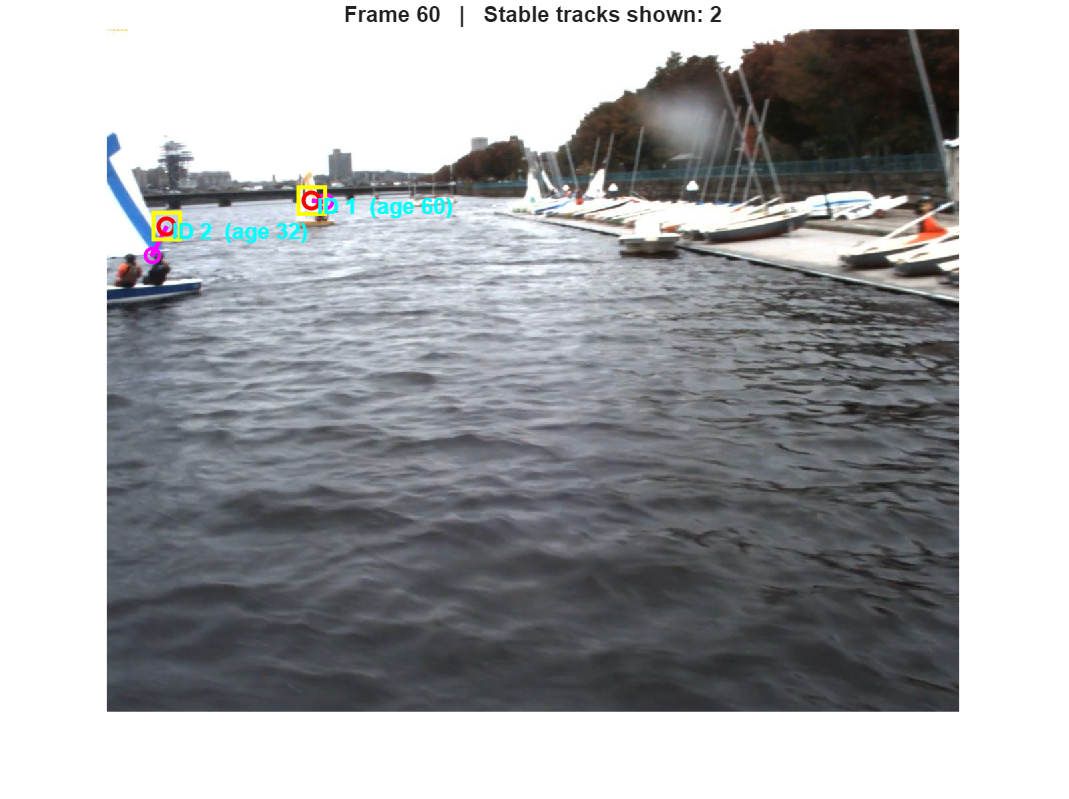

    %% Parameters
load 'single_class_ShipDetector.mat'
videoFile = 'C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4';
frameRate = 12;

%% Persistent "nice" ID system (only assigned to long-lived tracks)
persistentIDMap = containers.Map('KeyType','double','ValueType','double');
nextPersistentID = 1;

%% Tracker – score logic usually gives cleaner behavior
tracker = trackerGNN( ...
    'TrackLogic',              'Score', ...
    'ConfirmationThreshold',   18, ...          % tune: 15–25; higher → confirms later
    'DeletionThreshold',       -2, ...
    'AssignmentThreshold',     220, ...
    'FilterInitializationFcn', @initcvkf, ...
    'MaxNumTracks',            200, ...
    'MaxNumDetections',        100);

%% Video
video = VideoReader(videoFile);
frameCount = 0;

%% Main loop
while hasFrame(video)
    frame = readFrame(video);
    frameCount = frameCount + 1;
    currentTime = frameCount;

    %% Detect
    [bboxes, ~, ~] = detect(ship_DetectorV1, frame);

    if ~isempty(bboxes)
        centroids = [bboxes(:,1) + bboxes(:,3)/2, bboxes(:,2) + bboxes(:,4)/2];
        numDets = size(centroids,1);
        detections = repmat(objectDetection(0,[0;0]), numDets, 1);

        for j = 1:numDets
            meas = centroids(j,:)';
            detections(j) = objectDetection(currentTime, meas, ...
                'MeasurementNoise', 25*eye(2), ...
                'ObjectClassID', 1);
        end
    else
        detections = [];
    end

    %% Update tracker
    tracks = tracker(detections, currentTime);

    %% Display – ONLY tracks with Age >= 10 AND confirmed
    imshow(frame);
    hold on;
    
    showThese = tracks( [tracks.IsConfirmed] & [tracks.Age] >= 10 );
    
    for i = 1:length(showThese)
        t = showThese(i);
    
        origID = t.TrackID;
    
        % Assign persistent ID only to long-lived tracks
        if ~isKey(persistentIDMap, origID)
            persistentIDMap(origID) = nextPersistentID;
            nextPersistentID = nextPersistentID + 1;
        end
        displayID = persistentIDMap(origID);
    
        % ── Current position ───────────────────────────────
        state = t.State;
        pos  = state([1 3])';           % [x y]
    
        % ── Velocity vector ────────────────────────────────
        vel  = state([2 4])';           % [vx vy]
    
        % You can scale the arrow length (very important!)
        % Try values between 5 – 30 depending on your video scale & speed
        arrow_scale = 12;               % ← ← ← tune this value !!
    
        vel_end = pos + vel * arrow_scale;
    
        % Draw velocity arrow
        quiver(pos(1), pos(2), ...      % start point
               vel_end(1)-pos(1), ...   % delta x
               vel_end(2)-pos(2), ...   % delta y
               'Color', 'm', ...        % magenta = very visible
               'LineWidth', 2.2, ...
               'MaxHeadSize', 0.4, ...
               'AutoScale', 'off');     % very important!!
    
        % Optional: little circle at the tip of the arrow
        plot(vel_end(1), vel_end(2), 'mo', 'MarkerSize', 7, 'LineWidth', 1.8);
    
        % ── Main visualization ─────────────────────────────
        rectangle('Position', [pos-20, 40, 40], ...
            'EdgeColor','yellow','LineWidth',2);
    
        plot(pos(1), pos(2), 'ro','MarkerSize',8,'LineWidth',2);
    
        text(pos(1)+8, pos(2)+8, sprintf('ID %d  (age %d)', displayID, t.Age), ...
            'Color','cyan','FontSize',11,'FontWeight','bold');
    
    end
    
    hold off;
    title(sprintf('Frame %d   |   Stable tracks shown: %d', ...
                  frameCount, length(showThese)));
    drawnow;
end

Let's save the above output:

%% Parameters
load 'single_class_ShipDetector.mat'
videoFile = 'C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4';
frameRate = 12;

%% Persistent "nice" ID system
persistentIDMap = containers.Map('KeyType','double','ValueType','double');
nextPersistentID = 1;

%% Tracker
tracker = trackerGNN( ...
    'TrackLogic',              'Score', ...
    'ConfirmationThreshold',   18, ...
    'DeletionThreshold',       -2, ...
    'AssignmentThreshold',     220, ...
    'FilterInitializationFcn', @initcvkf, ...
    'MaxNumTracks',            200, ...
    'MaxNumDetections',        100);

%% Video input & output setup
rightVideo = VideoReader(videoFile);

% Output file – adjust path/folder as needed
[~, name, ~] = fileparts(videoFile);
outFile = 'C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\Outputs';


v = VideoWriter(outFile, 'MPEG-4');
v.FrameRate = rightVideo.FrameRate;
open(v);

frameCount = 0;

%% Main loop
while hasFrame(rightVideo)
    frame = readFrame(rightVideo);
    frameCount = frameCount + 1;
    currentTime = frameCount;

    %% Detect
    [bboxes, ~, ~] = detect(ship_DetectorV1, frame);

    detections = {};  % always cell array (prevents locked state error)

    if ~isempty(bboxes)
        centroids = [bboxes(:,1) + bboxes(:,3)/2, bboxes(:,2) + bboxes(:,4)/2];
        numDets = size(centroids,1);

        detections = cell(numDets, 1);

        for j = 1:numDets
            meas = centroids(j,:)';
            detections{j} = objectDetection(currentTime, meas, ...
                'MeasurementNoise', 25*eye(2), ...
                'ObjectClassID', 1, ...
                'ObjectAttributes', struct('BoundingBox', bboxes(j,:)));  % ← store original bbox
        end
    end

    %% Update tracker
    confirmedTracks = tracker(detections, currentTime);

    %% Create annotated frame
    annotatedFrame = frame;

    % Only show stable tracks (confirmed + at least 10 detections received)
    showThese = confirmedTracks( [confirmedTracks.IsConfirmed] & [confirmedTracks.Age] >= 10 );

    for i = 1:length(showThese)
        t = showThese(i);

        origID = t.TrackID;

        % Assign persistent display ID
        if ~isKey(persistentIDMap, origID)
            persistentIDMap(origID) = nextPersistentID;
            nextPersistentID = nextPersistentID + 1;
        end
        displayID = persistentIDMap(origID);

        state = t.State;
        pos = state([1 3])';   % predicted [x y]
        vel  = state([2 4])';  % [vx vy]

        % ── Velocity arrow ────────────────────────────────
        arrow_scale = 12;
        vel_end = pos + vel * arrow_scale;

        annotatedFrame = insertShape(annotatedFrame, 'Line', ...
            [pos(1), pos(2), vel_end(1), vel_end(2)], ...
            'Color', 'magenta', 'LineWidth', 3);

        annotatedFrame = insertShape(annotatedFrame, 'FilledCircle', ...
            [vel_end(1), vel_end(2), 6], 'Color', 'magenta');

        % ── Red dot at predicted center ───────────────────
        annotatedFrame = insertShape(annotatedFrame, 'FilledCircle', ...
            [pos(1), pos(2), 5], 'Color', 'red');

        % ── Bounding box ──────────────────────────────────
        if ~isempty(t.ObjectAttributes) && isfield(t.ObjectAttributes, 'BoundingBox')
            % Use most recent assigned bounding box
            bbox = t.ObjectAttributes.BoundingBox;
        else
            % Fallback: small box around predicted position (during coasting)
            bbox = [pos(1)-25, pos(2)-25, 50, 50];
        end

        annotatedFrame = insertShape(annotatedFrame, 'Rectangle', ...
            bbox, 'Color', 'yellow', 'LineWidth', 3);

        % ── Text label above or beside the box ────────────
        labelStr = sprintf('ID %d  age %d', displayID, t.Age);
        textPos = [bbox(1), bbox(2) - 20];  % above the box

        annotatedFrame = insertText(annotatedFrame, textPos, ...
            labelStr, ...
            'FontSize', 14, ...
            'BoxColor', 'black', ...
            'BoxOpacity', 0.6, ...
            'TextColor', 'cyan', ...
            'AnchorPoint', 'LeftBottom');
    end

    %% Optional live preview (comment out for faster processing)
    % imshow(annotatedFrame);
    % title(sprintf('Frame %d   |   Stable tracks: %d', frameCount, length(showThese)));
    % drawnow;

    %% Save frame
    writeVideo(v, annotatedFrame);
end

%% Clean up
close(v);
disp(['Output video saved to: ' outFile]);